# Simulación de Sistemas Eléctricos

# Actividad 10: Modelo de predicción con multiples Var. y Filtros

- **Variables independientes (x1,....,xn): Energía, Voltaje......,etc. en t=t0 (Valor actual)**

- **Variable dependiente (f(x)): Energía en t=to+dt (Valor siguiente); dt=1seg**

- **Frecuencia de muestreo de los datos: 1 muestra por segundo (sps)**

- **Venta temporal de predicción: (dt=1día)**

Nombres:

- Estudiante 1: VA

- Estudiante 2: VA

Contenido:

- Descargar datos (.csv) desde desde repositorio (DataPort)

- **Paper: **[https://doi.org/10.1016/j.procs.2022.07.035](https://doi.org/10.1016/j.procs.2022.07.035)

- **Dataset:** [https://ieee-dataport.org/open-access/data-server-energy-consumption-dataset](https://ieee-dataport.org/open-access/data-server-energy-consumption-dataset)

- **Codigo Matlab:** [https://github.com/vasanza/EnergyConsumptionPrediction](https://github.com/vasanza/EnergyConsumptionPrediction)

- **Funciones de Matlab:** [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

# Preprocesamiento (*)

- **1.- Leer el archivo .csv usando Matlab y graficar los datos**

- **2.- Filtrar los datos**

- **3.- Cambiar la frecuencia de muestreo de los datos (1 muestra por dia)**

- **4.- Adecuador el dataset con la var. independientes (x1,...,xn) y la var. dependiente f(x)**

# Extracción de características (*)

- **Pendiente**

# Selección de características

- **5.- Usar la matriz de correlación para eliminar del dataset var. redundantes **

# Modelo de predicción

- **6.- Dataset de training (70%) y testing (30%)**

- **7.- ToolBox de Matlab - Regression Learner (24 algoritmos)**

- **8.- Seleccionar el modelo que tiene un menor error de predicción**

- **9.- Exportar la función del mejor modelo**

- **10.- Calcular el error de predicción usando el dataset de testing**

- **Nota: realizar la prediccion en Minutos y horas <-------------------------------------- Tarea**

- **(*) Despues:**   

-     Invrementar las características temporales

#### **Eliminar datos de memoria y command window**

clear; %Borrar el korspace
clc; %Borrar el command window

#### Configuración de carpeta /src para librerias

%nombre de la carpeta donde estan los codigos
addpath(genpath('./src'));

**Configuranción de carpeta de /data para datasets**

%Nombre de la carpeta donde estan los archvios csv
datapath=fullfile('./data/');
filenames=FindCSV(datapath);

# **1.- Leer el archivo .csv usando Matlab y graficar los datos**

%Esto es lo que se hace con datos .csv
data=readtable(fullfile(datapath,filenames(1).name));
%clear dataRaw; %Borrar de memoria la variable que no usare despues
%Seleccionar las variables electricas de interes
data2=table2array(data(:,1:6)); % Convertir datos de string a float o int
data2(isnan(data2))=0; % Eliminar los datos NaN


#### Graficar todas las Variables

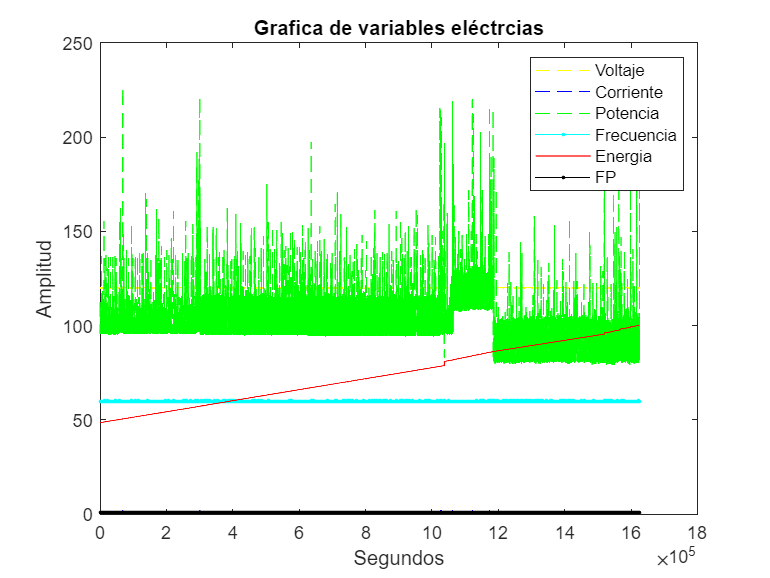

Voltaje=data2(:,1);
Corriente=data2(:,2);
Potencia=data2(:,3);%Columpa de potencia raw
Frecuencia=data2(:,4);
Energia=data2(:,5);
FP=data2(:,6);

figure %crear una nueva grafica
%plot(data2) %plotea la grafica 1
plot(Voltaje,'y--',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(Corriente,'b--',LineWidth=0.1);
plot(Potencia,'g--',LineWidth=0.01);
plot(Frecuencia,'c.-',LineWidth=0.1);
plot(Energia,'r',LineWidth=0.7);
plot(FP,'k.-',LineWidth=0.1);
hold off

title('Grafica de variables eléctrcias');
xlabel('Segundos');
ylabel('Amplitud');
legend('Voltaje','Corriente','Potencia','Frecuencia','Energia','FP');

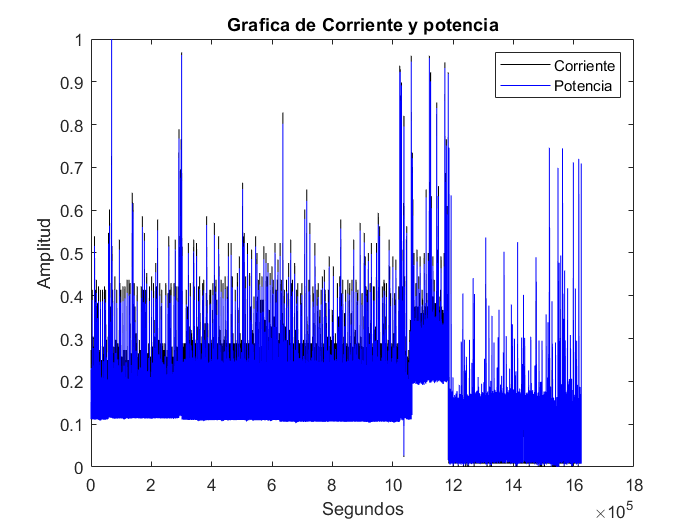

%Grafica de los datos normalizados
[DataNorm] = fNormalization(data2);

figure %crear una nueva grafica
plot(DataNorm(:,2),'k',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(DataNorm(:,3),'b',LineWidth=0.1);
hold off

title('Grafica de Corriente y potencia');
xlabel('Segundos');
ylabel('Amplitud');
legend('Corriente','Potencia');

%Limpiar del workspace variables no utilizadas
clear data;

# **2.- Filtrar los datos**

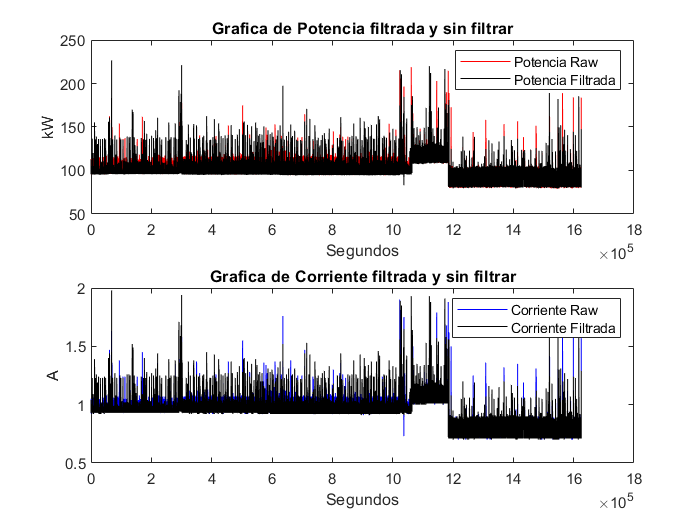

%Corriente
fCorriente=hampel(Corriente);
data2(:,2)=fCorriente;%<-------------------------------------------------
%Potencia
fPotencia=hampel(Potencia);
data2(:,3)=fPotencia;%sobrescribir la potencia raw por la filtrada<------


figure %crear una nueva grafica
subplot(2,1,1);
plot(Potencia(:,1),'r',LineWidth=0.01);
hold on %habilita plotear mas de una grafica en la misma figura
plot(data2(:,3),'k',LineWidth=0.1);
hold off
title('Grafica de Potencia filtrada y sin filtrar');
xlabel('Segundos');
ylabel('kW');
legend('Potencia Raw','Potencia Filtrada');

subplot(2,1,2);
plot(Corriente(:,1),'b',LineWidth=0.01);
hold on %habilita plotear mas de una grafica en la misma figura
plot(data2(:,2),'k',LineWidth=0.1);
hold off
title('Grafica de Corriente filtrada y sin filtrar');
xlabel('Segundos');
ylabel('A');
legend('Corriente Raw','Corriente Filtrada');

# **2.- Cambiar la frecuencia de muestreo de los datos (1 muestra por dia)**

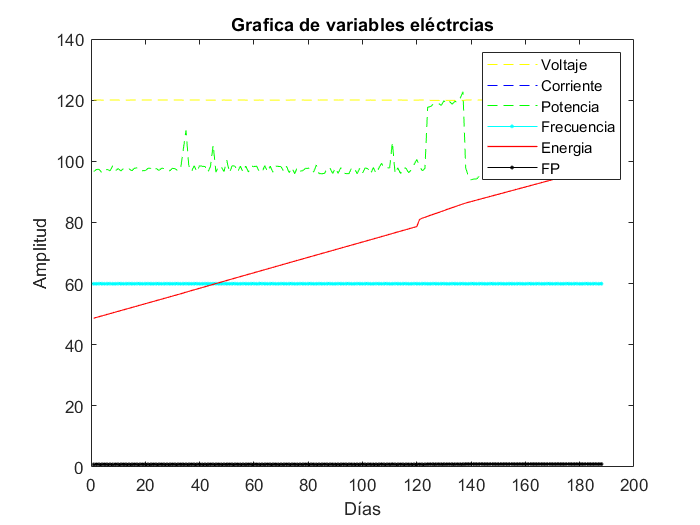

win=3600*24; %dado a que los datos estan en segundos y queremos llevarlo a dias
data2Mean=fData_MeanWin(data2,win);%60 segundos 

figure %crear una nueva grafica
plot(data2Mean(:,1),'y--',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(data2Mean(:,2),'b--',LineWidth=0.1);
plot(data2Mean(:,3),'g--',LineWidth=0.01);
plot(data2Mean(:,4),'c.-',LineWidth=0.1);
plot(data2Mean(:,5),'r',LineWidth=0.7);
plot(data2Mean(:,6),'k.-',LineWidth=0.1);
hold off


title('Grafica de variables eléctrcias');
xlabel('Días');
ylabel('Amplitud');
legend('Voltaje','Corriente','Potencia','Frecuencia','Energia','FP');

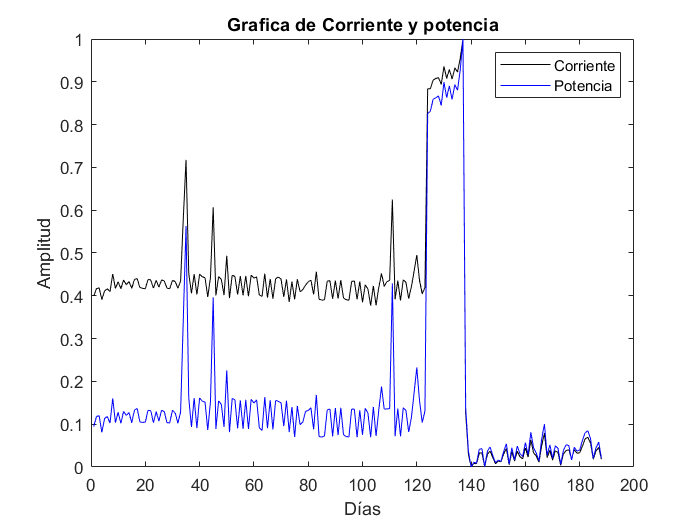

%Grafica de los datos normalizados
[DataNorm2] = fNormalization(data2Mean);

figure %crear una nueva grafica
plot(DataNorm2(:,2),'k',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(DataNorm2(:,3),'b',LineWidth=0.1);
hold off
title('Grafica de Corriente y potencia');
xlabel('Días');
ylabel('Amplitud');
legend('Corriente','Potencia');

%Limpiar del workspace variables no utilizadas
clear data2; clear FP; clear Potencia; clear Frecuencia; clear Energia;
 clear Corriente;clear Voltaje;clear win;

# **3.- Adecuador el dataset con la var. independientes (x1,...,xn) y la var. dependiente f(x)**

**Variables independientes (x1,....,xn): Energía, Voltaje......,etc. en t=t0 (Valor actual)**

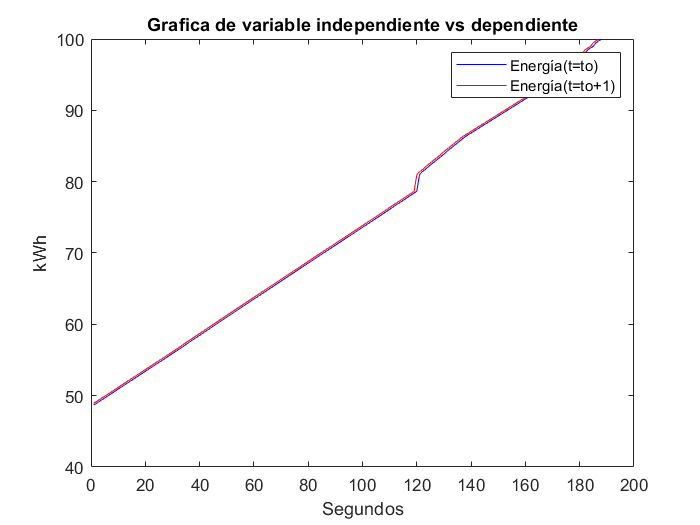

Voltaje=data2Mean(:,1);
Corriente=data2Mean(:,2);
Potencia=data2Mean(:,3);
Frecuencia=data2Mean(:,4);
Energia=data2Mean(:,5);
FP=data2Mean(:,6);
 
 % Variables independientes (x1,....,xn) en tiempo t=t0
input=[Voltaje(1:size(Voltaje,1)-1,1) Corriente(1:size(Corriente,1)-1,1)...
    Potencia(1:size(Potencia,1)-1,1) Frecuencia(1:size(Frecuencia,1)-1,1)...
    Energia(1:size(Energia,1)-1,1) FP(1:size(FP,1)-1,1)];
% Variable dependient f(x) en el tiempo t=t0+dt (1 día)
output=Energia(2:size(Energia,1),1);

%Primeras columnas son las entradas o varianles independientes
%La ultima columna es la salida o variable dependiente
dataset=[input output];

 figure %crear una nueva grafica
 plot(Energia(:,1),'b',LineWidth=0.1);
 hold on %habilita plotear mas de una grafica en la misma figura
 plot(output(:,1),'r',LineWidth=0.1);
 hold off
% 
 title('Grafica de variable independiente vs dependiente');
 xlabel('Dias');
 ylabel('kWh');
 legend('Energía(t=to)','Energía(t=to+1)');

 %Limpiar del workspace variables no utilizadas
clear FP; clear Potencia; clear Frecuencia; clear Energia;
clear Corriente;clear Voltaje; clear data2Mean;
clear input; clear output;

# **4.- Usar la matriz de correlación para eliminar del dataset var. redundantes **

threshold=0.80;%<---------------------------------------------------------
DataFeatures=dataset(:,1:6);%no incluir la variable de salida
FeaturesLabels={'Voltaje','Corriente','Potencia','Frcuencia','Energia','FP'};
corr_matr = corrcoef(DataFeatures)

corr_matr =     1.0000   -0.7873   -0.9523   -0.0227   -0.0556    0.1023
   -0.7873    1.0000    0.8086    0.1490   -0.4696   -0.6489
   -0.9523    0.8086    1.0000    0.0664    0.0437   -0.0773
   -0.0227    0.1490    0.0664    1.0000   -0.1707   -0.1708
   -0.0556   -0.4696    0.0437   -0.1707    1.0000    0.8600
    0.1023   -0.6489   -0.0773   -0.1708    0.8600    1.0000


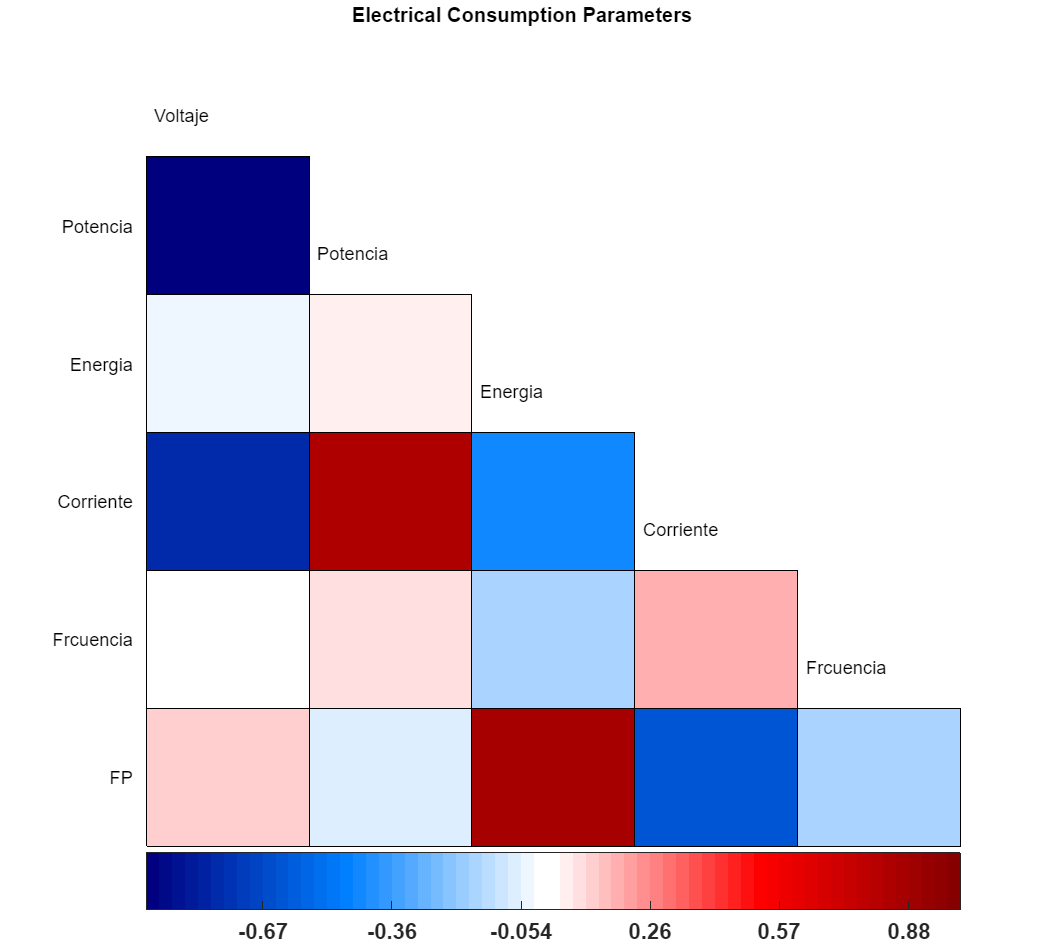

NewDataFeatures =   120.0340    0.9349   59.9677   48.6804
  120.0303    0.9402   59.9647   48.9284
  120.0342    0.9408   59.9676   49.1773
  120.0184    0.9322   59.9689   49.4258
  120.0252    0.9386   59.9681   49.6735
  120.0305    0.9401   59.9703   49.9221
  120.0415    0.9380   59.9688   50.1706
  120.0426    0.9508   59.9699   50.4214
  120.0480    0.9404   59.9717   50.6713
  120.0280    0.9452   59.9679   50.9210


NewFeaturesLabels = 1×4 cell array
    {'Voltaje'}    {'Corriente'}    {'Frcuencia'}    {'Energia'}


LabelsRemove = 1×2 cell array
    {'Potencia'}    {'FP'}


[NewDataFeatures,NewFeaturesLabels,LabelsRemove] = Feature_Selection(DataFeatures,FeaturesLabels,threshold)

# **4.- Dataset de training (70%) y testing (30%)**

dataset2=[NewDataFeatures dataset(:,7)];
%70 de entrenamiento y 30% de testing
Training=dataset2(1:round(size(dataset2,1)*0.7),:);% fila 1 hasta la fila del 70% de todas las filas
%desde la fila del 70% de todas las filas hasta la ultima fila
Testing=dataset2(round(size(dataset2,1)*0.7)+1:round(size(dataset2,1)),:);

 %Limpiar del workspace variables no utilizadas
clear NewDataFeatures; clear DataFeatures;
clear threshold; clear NewFeaturesLabels; clear LabelsRemove;
clear dataset2; clear FeaturesLabels;

# **5.- ToolBox de Matlab - Regression Learner (24 algoritmos)**

regressionLearner

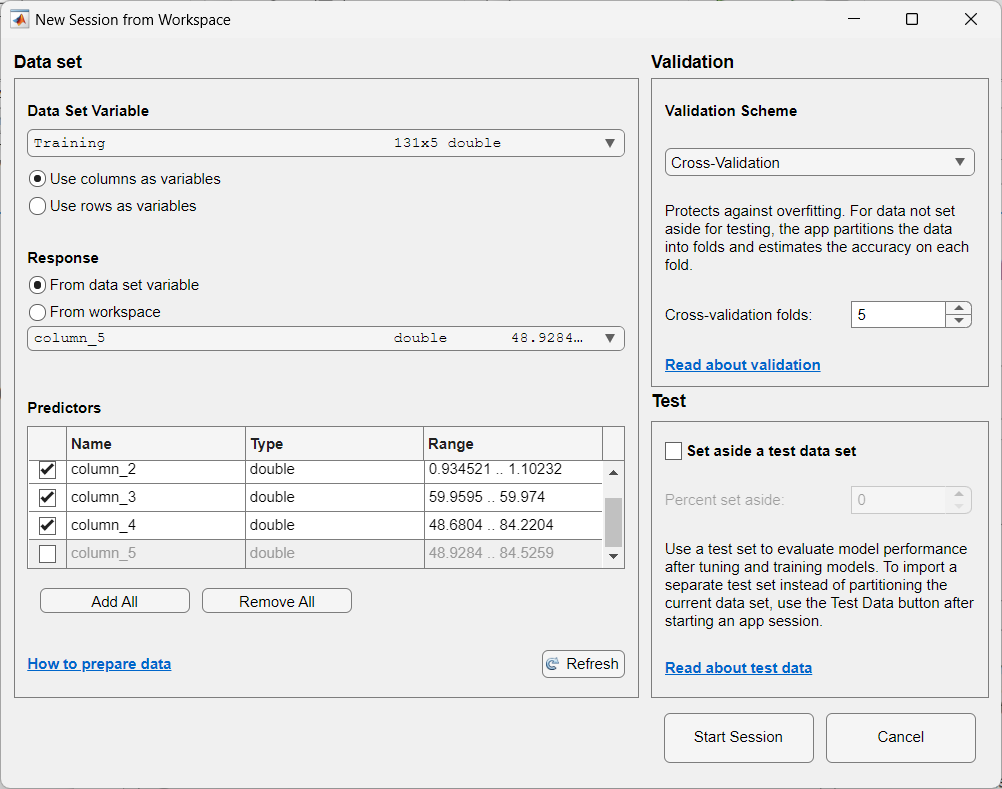

# **6.- Seleccionar el modelo que tiene un menor error de predicción**

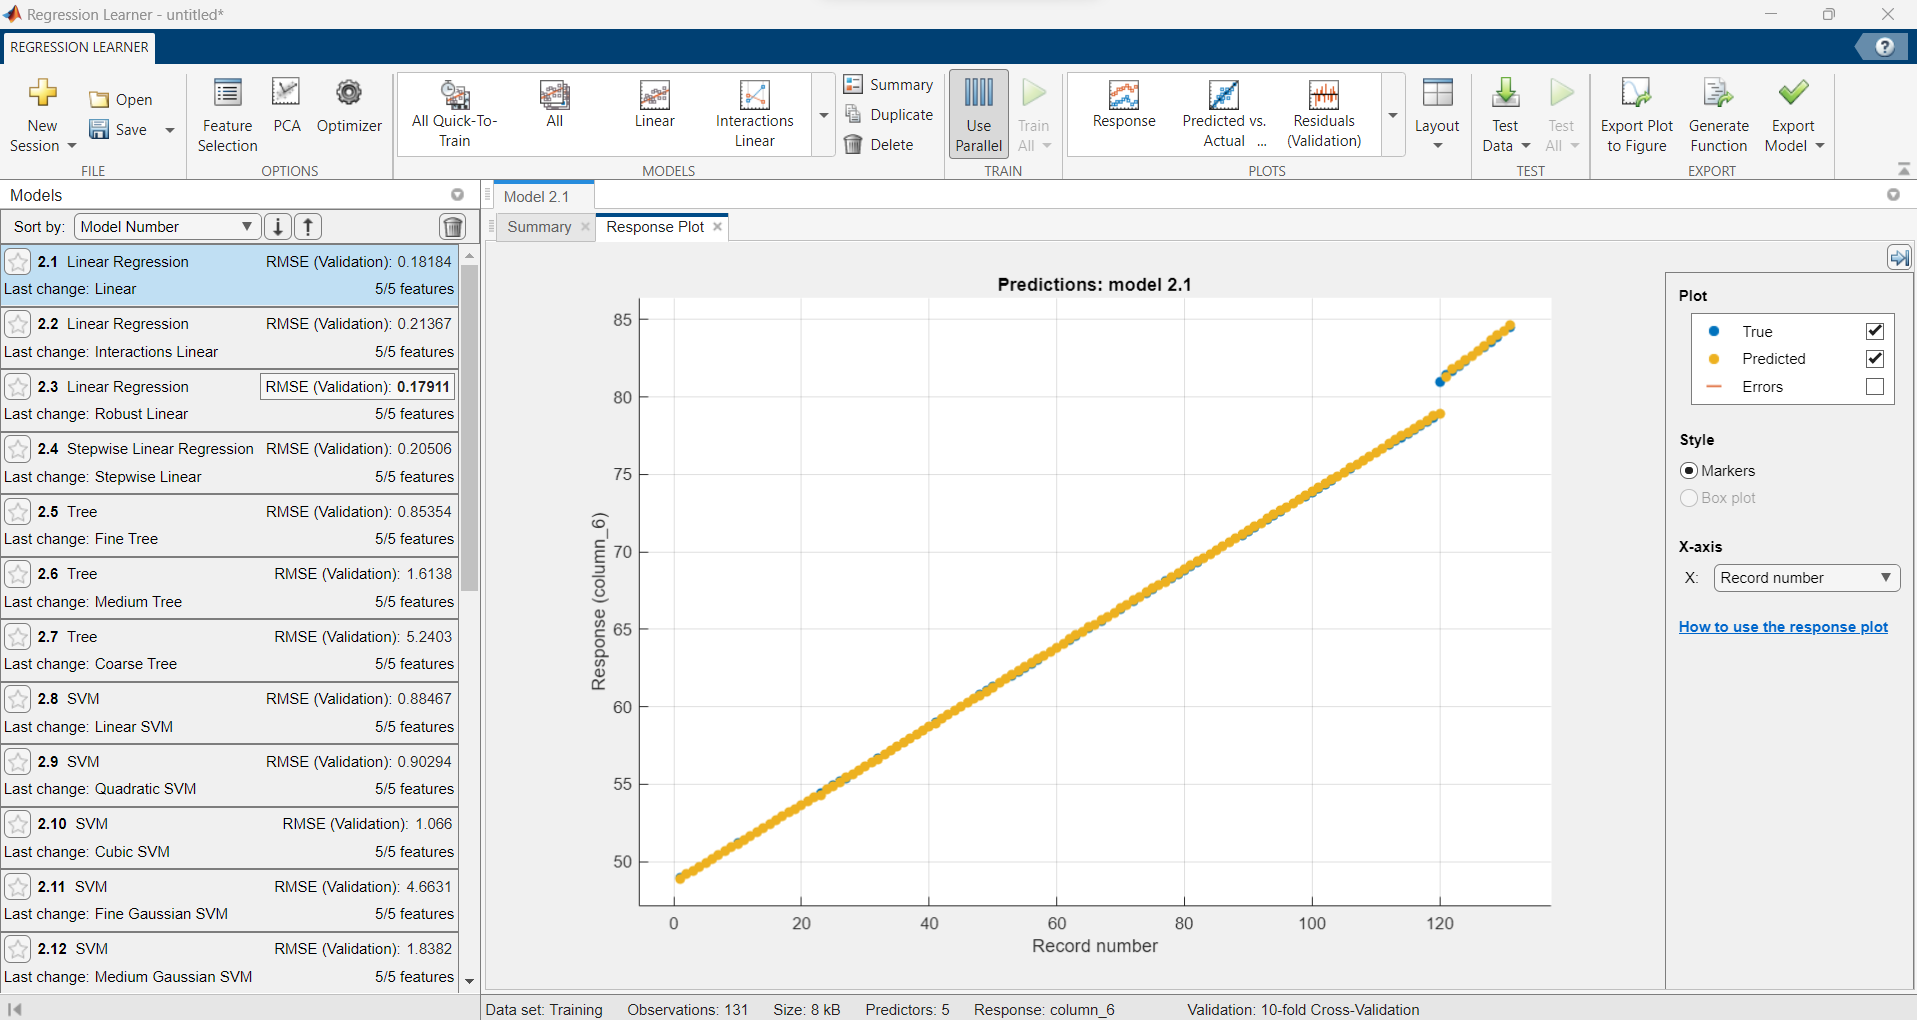

# **7.- Exportar la función del mejor modelo**

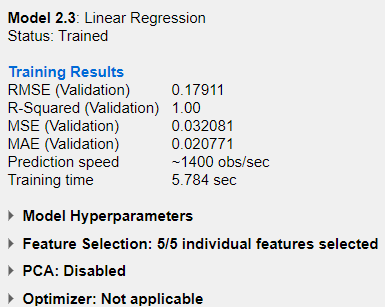

%Gaussian Process Regression
[trainedModel, validationRMSE] = trainRegressionModel_LR(Training)

trainedModel = struct with fields:
      predictFcn: @(x)linearModelPredictFcn(predictorExtractionFcn(x))
     LinearModel: [1×1 LinearModel]
           About: 'This struct is a trained model exported from Regression Learner R2022a.'
    HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  yfit = c.predictFcn(X) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 4 columns because this model was trained using 4 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 0.1792

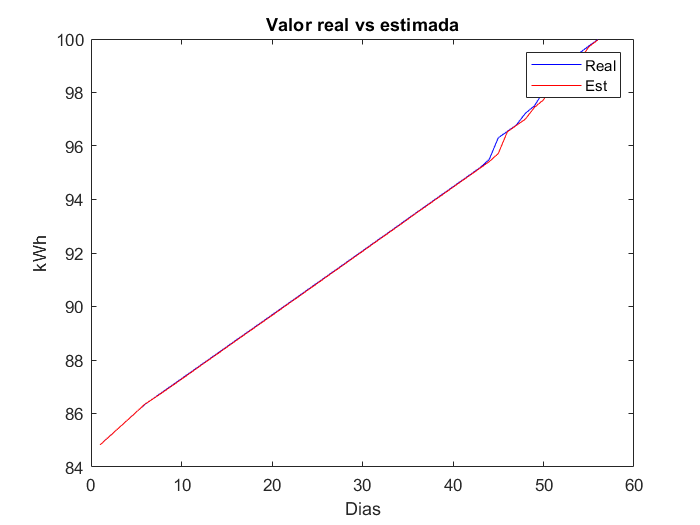

%[trainedModel, validationRMSE] = trainRegressionModel_fLR(Training)
%Aqui le datos al modelo solo las varibles de entrada
EnergiaEst=trainedModel.predictFcn(Testing(:,1:4));%Sin la salida ya que el modelo lo predice
EnergiaReal=Testing(:,5); %<------------------------ Energía Real

 figure %crear una nueva grafica
 plot(EnergiaReal,'b',LineWidth=0.1);
 hold on %habilita plotear mas de una grafica en la misma figura
 plot(EnergiaEst,'r',LineWidth=0.1);
 hold off
% 
 title('Valor real vs estimada');
 xlabel('Dias');
 ylabel('kWh');
 legend('Real','Est');

# **8.- Calcular el error de predicción usando el dataset de testing**

%[rmse,mse,r2] = fBar_RmseMseR2(EnergiaEst,Testing(:,2))
%r2 = fR2(EnergiaEst,EnergiaReal)
rmse = sqrt(immse(EnergiaEst,EnergiaReal))%0.2103 %0.1126

rmse = 0.1078

mse = immse(EnergiaEst,EnergiaReal)%0.0442 %0.0127

mse = 0.0116

mae = sum(abs(EnergiaEst-EnergiaReal)/length(EnergiaEst))%0.1988 %0.0559

mae = 0.0468